# Aircraft Selection via DOP

## File Loading

% Load data
clear; clc;
% Helper functions' path
addpath('geodesy');
addpath('src');

% Note that for training we have results as well
training = false;

if training
    DIRECTORY_NUM = '1';
    MEASUREMENTS_DIR = sprintf('../datasets/round_1/%s/training_%s_category_1', DIRECTORY_NUM, DIRECTORY_NUM);
    RESULTS_DIR = sprintf('../datasets/round_1/%s/training_%s_category_1_result', DIRECTORY_NUM, DIRECTORY_NUM);

    % We have 2 sets: measurements and results (to compare our approach to)
    MEASUREMENTS_CSV = sprintf('training_%s_category_1.csv', DIRECTORY_NUM);
    SENSORS_CSV = 'sensors.csv';
    RESULTS_CSV = 'training_{}_category_1_result.csv';
    
    BAD_SENSORS = [19]
else
    MEASUREMENTS_DIR = '../datasets/round_2';
    RESULTS_DIR = '';

    % We have 2 sets: measurements and results (to compare our approach to)
    MEASUREMENTS_CSV = 'round2_competition.csv';
    SENSORS_CSV = 'round2_sensors.csv';
    RESULTS_CSV = '';
    
    BAD_SENSORS = [19];
end

CACHE = 'workspace_rtl.mat';

if isfile(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE))
    load(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE), 'ddoa', 'aircraft', 'sensors');
else
    f = true;
    fraction = 0.1;
    [aircraft, sensors] = loadDataRTL(MEASUREMENTS_DIR, MEASUREMENTS_CSV, SENSORS_CSV, f, fraction);
    ddoa = getddoa(aircraft);
    save(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE), 'ddoa', 'aircraft', 'sensors');
end

% Speed of light is 299792458 m/s
c = 299792458;
ddoa.ddoam = ddoa.ddoa * 1e-9 * c;

backup_sensors = sensors; backup_aircraft = aircraft; backup_ddoa = ddoa;

% % Ground truth sensor
verified = [48.09379, 11.63527, 544]; % indoor
verified = [verified; 50.7015, 8.314159, 270]; % indoor
verified = [verified; 49.850256222468396, 6.808953881263733, 230]; % outdoor
verified = [verified; 51.177688, -0.923107, 150]; % outdoor
verified = [verified; 51.1704132072078, 0.8729153479826783, 1200]; % indoor
verified = [verified; 49.12702033, 8.51932350, 125]; % outdoor
verified = [verified; 50.255839, 8.676054, 237.13]; % indoor
verified = [verified; 49.4051387, 11.1761876, 341]; % indoor

sensorIds = [607, 578, 363, 463, 357, 584, 83, 614];

## Initial Data preparation

% Computing cartesian coordinates
xyz = llh2ecef([aircraft.latitude, aircraft.longitude, aircraft.geoAltitude]);
aircraft.x = xyz(:,1);
aircraft.y = xyz(:,2);
aircraft.z = xyz(:,3);

% Let's only keep sensors that appear on the measurements
keep = ismember(sensors.serial,ddoa.s1) | ismember(sensors.serial,ddoa.s2);
sensors = sensors(keep,:);

% Let's also compute the cartesian coordinates
xyz = llh2ecef([sensors.latitude, sensors.longitude, sensors.height]);
sensors.x = xyz(:,1);
sensors.y = xyz(:,2);
sensors.z = xyz(:,3);

% Radarcape 'good' sensors
reference = sensors((strcmp(sensors.type,'Radarcape').*strcmp(sensors.good,'TRUE')) == 1,:);
reference(BAD_SENSORS,:) = [];

% Dump1090 sensors
unknown = sensors(ismember(sensors.serial,sensorIds),:);

% We can compute the errors between the measured and expected TDOAs
maskref = ismember(ddoa.s1, reference.serial, 'rows') | ismember(ddoa.s2, reference.serial, 'rows');
maskunk = ismember(ddoa.s1, unknown.serial, 'rows') | ismember(ddoa.s2, unknown.serial, 'rows');
ddoa = ddoa(maskref | maskunk,:);

[~,acId] = ismember(ddoa.id, aircraft.id, 'rows');
[~,s1Id] = ismember(ddoa.s1, sensors.serial, 'rows');
[~,s2Id] = ismember(ddoa.s2, sensors.serial, 'rows');

acd = table2array(aircraft(acId,{'x', 'y', 'z'}));
s1d = table2array(sensors(s1Id,{'x', 'y', 'z'}));
s2d = table2array(sensors(s2Id,{'x', 'y', 'z'}));

% Computation of TDOAs
d1 = ecef_distance(acd, s1d);
d2 = ecef_distance(acd, s2d);

exp = d1 - d2;
ddoa.exp = exp;
ddoa.err = exp - ddoa.ddoam;

## Removing some outliers

maskerr = ddoa.err > quantile(ddoa.err,0.01) & ddoa.err < quantile(ddoa.err,0.99);
ddoa = ddoa(maskerr,:);

%%% Removing unnecessary aircrafts
unique_ids = unique(ddoa.id);
maskair = ismember(aircraft.id,unique_ids);
aircraft = aircraft(maskair,:);

% First we need to cleanup the aircrafts
% We can get the time and distance the aircraft moved while it was seen by the
% system
% Then we remove all the sensors that have wrong measurements
aircraft_list = unique(aircraft.aircraft);

max_dist = zeros(length(aircraft_list),1);
max_time = zeros(length(aircraft_list),1);
for ii = 1:length(aircraft_list)
    acId = aircraft_list(ii);
    aircraftPath = aircraft(aircraft.aircraft == acId, :);
    
    if height(aircraftPath) > 1
        max_dist(ii) = norm(table2array(aircraftPath(end,{'x','y','z'})) - table2array(aircraftPath(1,{'x','y','z'})))/1000;
        max_time(ii) = norm(table2array(aircraftPath(end,{'timeAtServer'})) - table2array(aircraftPath(1,{'timeAtServer'})));
    else
        max_dist(ii) = 0;
        max_time(ii) = 0;
    end
end

g = max_dist ~= 0;
good_aircraft = aircraft_list(g);

% Filter aircraft
maskair = ismember(aircraft.aircraft,good_aircraft);
aircraft = aircraft(maskair,:);

% Filter ddoa
maskddoa = ismember(ddoa.id,aircraft.id);
ddoa = ddoa(maskddoa,:);

## Optimization approaches (with offset)

In this one, we will use all sensors but one and optimize the position (imitating a user)

### Precomputing the offsets

The observation is that offsets remain 'constant' throughtout time, so no need to divide by aircraft or time

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Linear least squares    
% We start with the C matrix
maskref = ismember(ddoa.s1,reference.serial) & ismember(ddoa.s2,reference.serial);
ddoaref = ddoa(maskref,:);

maskerr = ddoaref.err > quantile(ddoaref.err,0.05) & ddoaref.err < quantile(ddoaref.err,0.95);
ddoaref = ddoaref(maskerr,:);

C = zeros(height(ddoaref), height(reference));
for index = 1:height(reference)
    s = reference.serial(index);
    mask_positive = ddoaref.s1 == s;
    mask_negative = ddoaref.s2 == s;
    C(mask_positive, index) = 1;
    C(mask_negative, index) = -1;
end

% Now the d vector
d = -ddoaref.err;

% We set the lower and upper bounds
sigma = std(ddoaref.err);
% lb = [-1e-7;-5*sigma.*ones(height(reference)-1,1)];
% ub = [ 1e-7; 5*sigma.*ones(height(reference)-1,1)];
lb = [-1e-7; -inf.*ones(height(reference)-1,1)];
ub = [ 1e-7;  inf.*ones(height(reference)-1,1)];

offsets = lsqlin(C,d,[],[],[],[],lb,ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


reference.offsets = offsets;

### Selecting sensors

SELECT = 1;
sensor = unknown(SELECT,:);

% Selecting all rows
mask = (ddoa.s1 == sensor.serial) | (ddoa.s2 == sensor.serial);
maskg = (ismember(ddoa.s1,reference.serial) | ismember(ddoa.s2,reference.serial));
mask = mask & maskg;

ddoa_sensor_count = grpstats(ddoa(mask,:),{'s1','s2'});
ddoa_sensor_count = sortrows(ddoa_sensor_count,'GroupCount','descend');

% Loop parameters
numIter = 1; % Iterations per fraction and sensor
num_ref = 10; % Max number of reference sensors to use

Ng = min([height(ddoa_sensor_count), num_ref]);

indices = zeros(Ng,1);
for jj = 1:Ng
    if ddoa_sensor_count.s1(jj) == sensor.serial
        indices(jj) = find(reference.serial == ddoa_sensor_count.s2(jj));
    else
        indices(jj) = find(reference.serial == ddoa_sensor_count.s1(jj));
    end
end

ground = reference(indices,:);
ground.drift = zeros(height(ground),1);

% Let's filter the data
mask_s = ismember(ddoa.s1, sensor.serial, 'rows') | ismember(ddoa.s2, sensor.serial, 'rows');
mask_g = ismember(ddoa.s1, ground.serial, 'rows') | ismember(ddoa.s2, ground.serial, 'rows');
mask_s = mask_s & mask_g;
data = ddoa(mask_s,:);
data = sortrows(data,'id');

dt = sortrows(data,'id');

% We need the mean positions
unique_id = unique(data.id);
[~,idx,~] = intersect(aircraft.id,unique_id);
ac = aircraft(idx,:);

ac_color_hex = '#0064FF';
ac_color = sscanf(ac_color_hex(2:end),'%2x%2x%2x',[1 3])/255;

se_color_hex = '#FF6400';
se_color = sscanf(se_color_hex(2:end),'%2x%2x%2x',[1 3])/255;

sensor_color_hex = '#f2ff00';
sensor_color = sscanf(sensor_color_hex(2:end),'%2x%2x%2x',[1 3])/255;

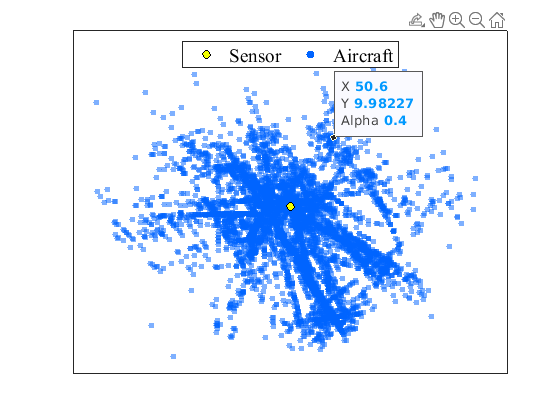

% All aircraft
figure();
hold on; box on;

set(gca,'BoxStyle', 'full');
set(gca,'FontSize',16,'FontName','Times');
set(gca,'XTick',[]);
set(gca,'YTick',[]);

% Aircraft
h2 = scatter(ac.latitude, ac.longitude, 20, ac_color, 'filled');
h2.AlphaData = 0.4*ones(size(ac,1),1);
h2.MarkerFaceAlpha = 'flat';

% Sensor
h1 = scatter(sensor.latitude, sensor.longitude, 40, sensor_color, 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);

xlim([48.5, 52]);
ylim([5.5,12]);

legend([h1,h2],'Sensor','Aircraft', 'Location','north','Orientation','horizontal');
hold off;

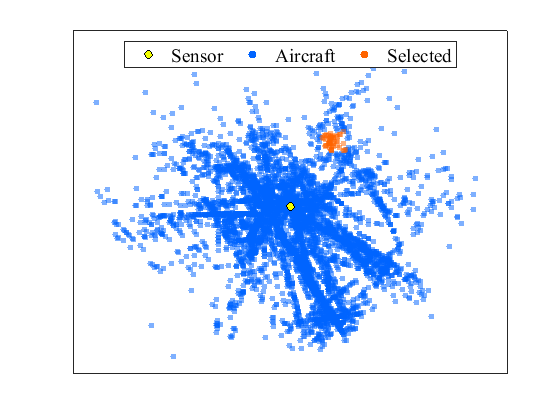

% Get data for the two circles
t = 0:0.1:2*pi; R = 0.2; x0 = 50.6; y0 = 9.9;
x = x0 + .5*R * cos(t);
y = y0 +    R * sin(t);

acidx = ac.latitude > min(x) & ac.latitude < max(x);
acidy = ac.longitude > min(y) & ac.longitude < max(y);

acids = acidx & acidy;
acbad = ac(acids,:);
acgood = ac(~acids,:);

% Bad GDOP
figure();
hold on; box on;

set(gca,'BoxStyle', 'full');
set(gca,'FontSize',16,'FontName','Times');
set(gca,'XTick',[]);
set(gca,'YTick',[]);

% Aircraft
h2 = scatter(acgood.latitude, acgood.longitude, 20, ac_color, 'filled');
h2.AlphaData = 0.4*ones(size(acgood,1),1);
h2.MarkerFaceAlpha = 'flat';

h3 = scatter(acbad.latitude, acbad.longitude, 20, se_color, 'filled');
h3.AlphaData = 0.4*ones(size(acbad,1),1);
h3.MarkerFaceAlpha = 'flat';

% Sensor
h1 = scatter(sensor.latitude, sensor.longitude, 40, sensor_color, 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);

% Fill
% fill(x,y,se_color,'FaceAlpha',0.2, 'LineStyle','none');

xlim([48.5, 52]);
ylim([5.5,12]);

legend([h1,h2,h3],{'Sensor','Aircraft','Selected'},'Location','north','Orientation','horizontal');
hold off;

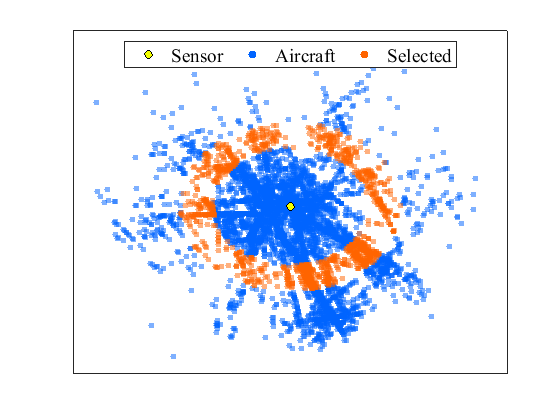

% Get data for the two circles
t = 0:0.1:2*pi; R = 1.6; x0 = sensor.latitude; y0 = sensor.longitude;
x = x0 + .53*R * cos(t);
y = y0 +    R * sin(t);

distac = sqrt(sum([1.8*(ac.latitude-x0),ac.longitude-y0].^2,2));

acids1 = distac < R;
acids2 = distac > R*.7;
acbad = ac(acids1&acids2,:);
acgood = ac(~(acids1&acids2),:);

% Bad GDOP
figure();
hold on; box on;

set(gca,'BoxStyle', 'full');
set(gca,'FontSize',16,'FontName','Times');
set(gca,'XTick',[]);
set(gca,'YTick',[]);

% Aircraft
h2 = scatter(acgood.latitude, acgood.longitude, 20, ac_color, 'filled');
h2.AlphaData = 0.4*ones(size(acgood,1),1);
h2.MarkerFaceAlpha = 'flat';

h3 = scatter(acbad.latitude, acbad.longitude, 20, se_color, 'filled');
h3.AlphaData = 0.4*ones(size(acbad,1),1);
h3.MarkerFaceAlpha = 'flat';

% Sensor
h1 = scatter(sensor.latitude, sensor.longitude, 40, sensor_color, 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);

% Fill
% fill(x,y,se_color,'FaceAlpha',0.2, 'LineStyle','none');

xlim([48.5, 52]);
ylim([5.5,12]);

legend([h1,h2,h3],{'Sensor','Aircraft','Selected'},'Location','north','Orientation','horizontal');
hold off;